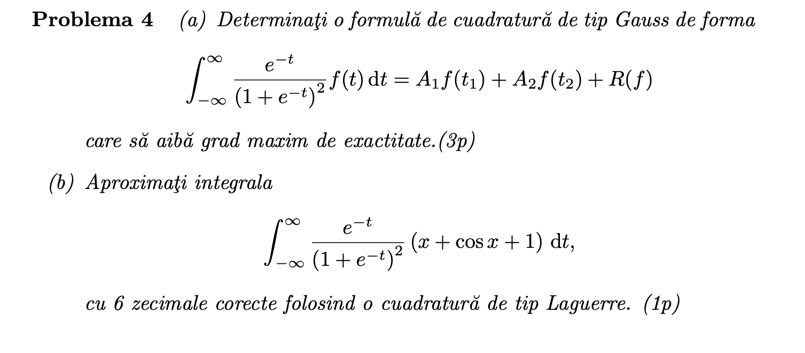

(*corectie*: t + cos(t) + 1 la b)

clear

## Solutie

### Primul subpunct

Fie functia pondere $w\left(t\right)=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }$. Observam ca $w\left(-t\right)=\frac{e^t }{{\left(1+e^t \right)}^2 }=\frac{e^t }{e^{2t} {\left(1+e^{-t} \right)}^2 }=\frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }=w\left(t\right)$, deci functia este para.

syms t;
w=exp(-t)/(1+exp(-t))^2

$$w = \frac{{\mathrm{e}}^{-t}}{{\left({\mathrm{e}}^{-t}+1\right)}^{2}}$$

Dorim sa gasim polinomul $\pi_2$ ortogonal pe $\left\lbrack -\infty ,\infty \right\rbrack$ pentru a atinge gradul maxim de exactitate. Deoarece polinomul are 2 radacini ($\left.t_1 ,t_2 \right)$, polinomul va avea gradul 2.

Deoarece ponderea este para, pentru ca $\int_{-\infty }^{\infty } w\left(t\right){\pi_2 \left(t\right)t}^{2k} \mathrm{dt}$ sa fie egal cu 0, deoarece $w\left(t\right)t^{2k}$ este o functie para (par * par = par), este necesar ca $\pi_2 \left(t\right)$ sa fie o functie impara $\Rightarrow$ radacinile lui sunt fie egale cu 0, fie simetrice, in orice caz, $t_1 =-t_2 =a$, deci $\pi_2 \left(t\right)=\left(t-a\right)\left(t+a\right)=t^2 -a^2$.


$$\pi_2 \perp 1\Rightarrow \int_{-\infty }^{\infty } w\left(t\right)\pi \left(t\right)\mathrm{dt}=0\Rightarrow \int_{-\infty }^{\infty } \frac{e^{-t} }{{\left(1+e^{-t} \right)}^2 }\left(t^2 -a^2 \right)\mathrm{dt}=0$$
 

syms a;
int(w * (t^2 - a^2), t, -inf, inf)

$$ans = \int_{-\infty }^{\infty }\left(-\frac{{\mathrm{e}}^{-t}\,\left(a^{2}-t^{2}\right)}{{\left({\mathrm{e}}^{-t}+1\right)}^{2}}\right)\mathrm{d}t$$

MATLAB-ul nu ne ajuta, vom rezolva in Wolfram Alpha:


$$\frac{1}{3}\left(\pi^2 -3a^2 \right)=0\Leftrightarrow a^2 =\frac{\pi^2 }{3}\Leftrightarrow a=\pm \frac{\pi \sqrt{3}}{3}\Rightarrow \pi_2 =t^2 -\frac{\pi^2 }{3}$$


clear a;
pi2=t^2-sym(pi)^2/3

$$pi2 = t^{2}-\frac{\pi^{2}}{3}$$

#### Ca alternativa scurta la ce e mai sus se poate folosi *orto_poly_sym.m*

pi2_like=simplify(orto_poly_sym(w,t,sym(-inf),sym(inf),2)) % tot cu WolframAlpha se calculeaza integralele

$$pi2\_like = t^{2}-\int_{-\infty }^{\infty }\frac{t^{2}\,{\mathrm{e}}^{t}}{{\left({\mathrm{e}}^{t}+1\right)}^{2}}\mathrm{d}t-\frac{t\,\int_{-\infty }^{\infty }\frac{t^{3}\,{\mathrm{e}}^{t}}{{\left({\mathrm{e}}^{t}+1\right)}^{2}}\mathrm{d}t}{\int_{-\infty }^{\infty }\frac{t^{2}\,{\mathrm{e}}^{t}}{{\left({\mathrm{e}}^{t}+1\right)}^{2}}\mathrm{d}t}$$

Avand polinomul, ne mai raman de aflat coeficientii $A_1 \;\mathrm{si}\;A_2$. Deoarece sunt 2 coeficienti, avem nevoie de primele 2 momente ale functiei:


$$\mu_0 =\int_{-\infty }^{\infty } w\left(t\right)t^0 \mathrm{dt}=A_1 +A_2$$


int(w, -inf, inf)

$$ans = 1$$

Deci $A_1 +A_2 =1$.

$\mu_1 =\int_{-\infty }^{\infty } w\left(t\right)t^1 \mathrm{dt}=A_1 \cdot a-A_2 \cdot a$. Deoarece $w\left(t\right)t^1$ este o functie impara (par * impar) $\Rightarrow \mu_1 =0\Leftrightarrow a\left(A_1 -A_2 \right)=0\Leftrightarrow A_1 =A_2$.

Din ultimele 2 relatii obtinem $A_1 =A_2 =\frac{1}{2}$.

Deci cuadratura Gauss obtinuta este $\int_{-\infty }^{\infty } w\left(t\right)f\left(t\right)\mathrm{dt}=\frac{f\left(\frac{\pi \sqrt{3}}{3}\right)+f\left(-\frac{\pi \sqrt{3}}{3}\right)}{2}+R\left(f\right)$.

[rest, gr_maxim]=rest_gauss_fara_f(w,-inf,inf,pi2,2);
simplify(rest)

$$ans = \frac{\int_{-\infty }^{\infty }\frac{{\mathrm{e}}^{-t}\,{\left(\pi^{2}-3\,t^{2}\right)}^{2}}{{\left({\mathrm{e}}^{-t}+1\right)}^{2}}\mathrm{d}t}{216}$$

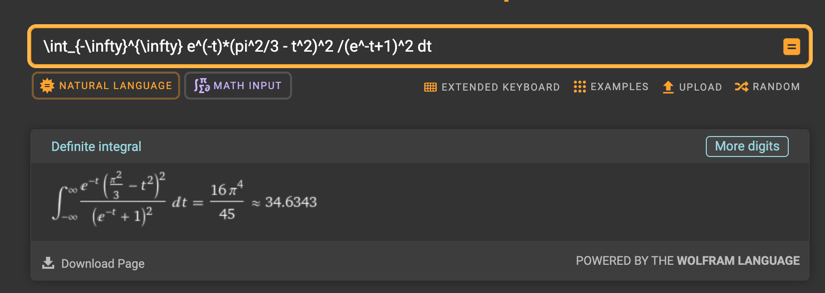

Deci $R\left(f\right)=\frac{16\pi^4 }{45\cdot 24}f^{\left(4\right)} \left(\xi \right)=\frac{2\pi^4 }{135}f^{\left(4\right)} \left(\xi \right)$, cu $\xi \in \left(-\infty ,\infty \right)$.

Gradul maxim de exactitate este 3. Verificam:

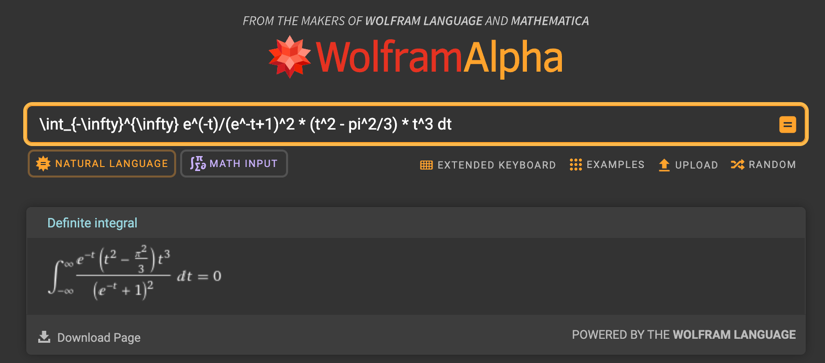

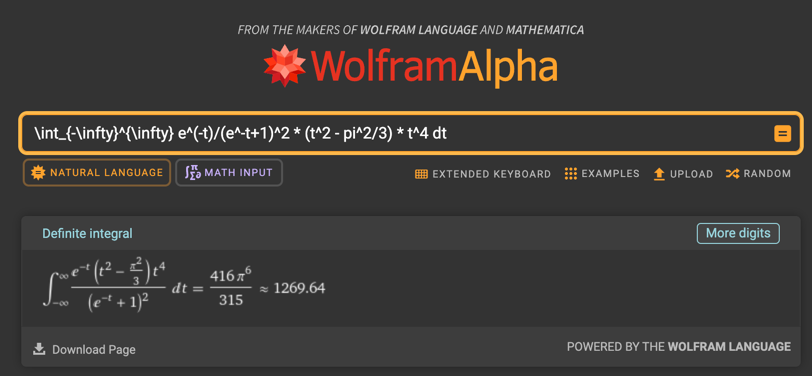

### Al doilea subpunct


$$I=\;\int_{-\infty }^{\infty } w\left(t\right)\left(t+\cos \left(t\right)+1\right)\mathrm{dt}$$


fn=matlabFunction(w*(t+cos(t)+1));
exp_quad=vpaintegral(fn, -inf, inf,'RelTol', 1e-12, 'AbsTol', 0)

$$exp\_quad = 1.27202905498$$

Cu schimbarea  de variabila $y=-t$ obtinem:


$$I=\int_{-\infty }^{\infty } w\left(-y\right)\left(-y+\cos \left(-y\right)+1\right)\mathrm{dy}=\int_{\infty }^{\infty } w\left(y\right)\left(-y+\cos \left(y\right)+1\right)\mathrm{dy}$$


Adunand cu integrala initiala, obtinem:


$$2I=\int_{-\infty }^{\infty } 2w\left(t\right)\left(\cos \left(t\right)+1\right)\mathrm{dt}\Leftrightarrow I=\int_{-\infty }^{\infty } w\left(t\right)\left(\cos \left(t\right)+1\right)\mathrm{dt}$$


Deoarece functia $\cos \left(t\right)+1$ este para si $w\left(t\right)$ este para, produsul lor va fi o functie para, deci:


$$I=2\int_0^{\infty } w\left(t\right)\left(\cos \left(t\right)+1\right)\mathrm{dt}=2\int_0^{\infty } e^{-t} \cdot \frac{\cos \left(t\right)+1}{{\left({1+e}^{-t} \right)}^2 }\mathrm{dt}$$


Putem aplica o cuadratura Gauss-Laguerre.

n=18;
f=@(x) (cos(x)+1)./(1+exp(-x)).^2

f = function_handle with value:
    @(x)(cos(x)+1)./(1+exp(-x)).^2


int=2*gauss_quad_num('Laguerre', f, n, 0)

int =            1.2720284186588


err=abs(exp_quad-int)

$$err = 0.00000063632332826936847636266004937366$$

Observam ca de la n=18 aproximatia noastra are 6 zecimale corecte.